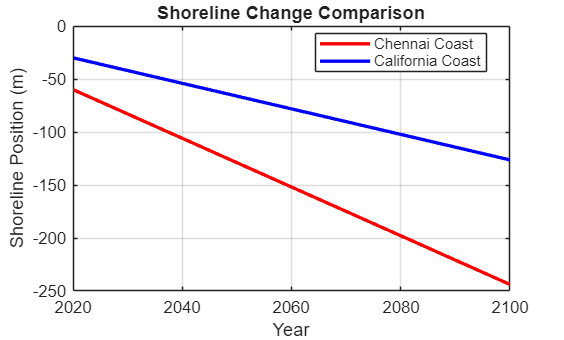

% =========================================================
% coastline_comparison_with_sealevel.m
% Comparison of Shoreline Change and Sea-Level Rise:
% Chennai Coast (India) vs California Coast (USA)
% =========================================================

clear; clc; close all;

%% ================= COMMON FUTURE PERIOD =================
future_year = (2020:2100)';

%% ================= CHENNAI COAST ========================

year_C = [1990 2000 2010 2020]';
shore_C = [0 -15 -35 -60]';      % strong erosion
SLR_C_2100 = 0.75;               % meters

L_C = 350;   % m
h_C = 9;     % m
B_C = 2;     % m

pC = polyfit(year_C, shore_C, 1);
rate_C = pC(1);

SLR_C = linspace(0, SLR_C_2100, length(future_year))';
R_C = (SLR_C .* L_C) ./ (h_C + B_C);

shore_future_C = shore_C(end) + rate_C*(future_year-2020) - R_C;

%% ================= CALIFORNIA COAST =====================

year_CA = [1990 2000 2010 2020]';
shore_CA = [0 -8 -18 -30]';      % moderate erosion
SLR_CA_2100 = 0.85;              % meters

L_CA = 250;   % m
h_CA = 10;    % m
B_CA = 3;     % m

pCA = polyfit(year_CA, shore_CA, 1);
rate_CA = pCA(1);

SLR_CA = linspace(0, SLR_CA_2100, length(future_year))';
R_CA = (SLR_CA .* L_CA) ./ (h_CA + B_CA);

shore_future_CA = shore_CA(end) + rate_CA*(future_year-2020) - R_CA;

%% ================= SHORELINE COMPARISON =================

figure
plot(future_year, shore_future_C, 'r', 'LineWidth', 2)
hold on
plot(future_year, shore_future_CA, 'b', 'LineWidth', 2)

xlabel('Year')
ylabel('Shoreline Position (m)')
title('Shoreline Change Comparison')
legend('Chennai Coast', 'California Coast', 'Location', 'best')
grid on

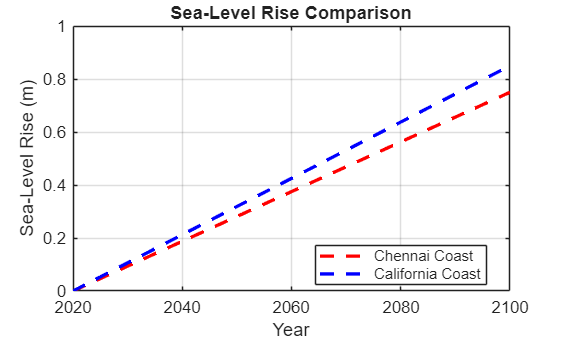


%% ================= SEA-LEVEL RISE COMPARISON =============

figure
plot(future_year, SLR_C, 'r--', 'LineWidth', 2)
hold on
plot(future_year, SLR_CA, 'b--', 'LineWidth', 2)

xlabel('Year')
ylabel('Sea-Level Rise (m)')
title('Sea-Level Rise Comparison')
legend('Chennai Coast', 'California Coast', 'Location', 'best')
grid on


%% ================= KEY RESULTS ==========================

disp('============================================')

disp('COASTLINE & SEA-LEVEL COMPARISON RESULTS')

COASTLINE & SEA-LEVEL COMPARISON RESULTS


disp('--------------------------------------------')

--------------------------------------------


disp(['Chennai erosion rate: ', num2str(rate_C), ' m/year'])

Chennai erosion rate: -2 m/year


disp(['California erosion rate: ', num2str(rate_CA), ' m/year'])

California erosion rate: -1 m/year


disp('--------------------------------------------')

--------------------------------------------


disp(['Sea-level rise in 2100 (Chennai): ', num2str(SLR_C_2100), ' m'])

Sea-level rise in 2100 (Chennai): 0.75 m


disp(['Sea-level rise in 2100 (California): ', num2str(SLR_CA_2100), ' m'])

Sea-level rise in 2100 (California): 0.85 m


disp('--------------------------------------------')

--------------------------------------------


disp(['Shoreline position in 2100 (Chennai): ', ...
      num2str(shore_future_C(end)), ' m'])

Shoreline position in 2100 (Chennai): -243.8636 m


disp(['Shoreline position in 2100 (California): ', ...
      num2str(shore_future_CA(end)), ' m'])

Shoreline position in 2100 (California): -126.3462 m


disp('============================================')


% ===================== END ===============================
